%  ___ ____  ____    _                                          
% |_ _|  _ \/ ___|  / \                                         
%  | || |_) \___ \ / _ \                                        
%  | ||  __/ ___) / ___ \                                       
% |___|_|   |____/_/   \_\      ____            _           _   
% |  _ \ _ __ ___  _ __   ___  |  _ \ _ __ ___ (_) ___  ___| |_ 
% | | | | '__/ _ \| '_ \ / _ \ | |_) | '__/ _ \| |/ _ \/ __| __|
% | |_| | | | (_) | | | |  __/ |  __/| | | (_) | |  __/ (__| |_ 
% |____/|_|  \___/|_| |_|\___| |_|   |_|  \___// |\___|\___|\__|
%  ____   ___ ____  _____      ____   ___ ___|__/  _            
% |___ \ / _ \___ \|___ /     |___ \ / _ \___ \| || |           
%   __) | | | |__) | |_ \ _____ __) | | | |__) | || |_          
%  / __/| |_| / __/ ___) |_____/ __/| |_| / __/|__   _|         
% |_____|\___/_____|____/     |_____|\___/_____|  |_|       

clc; close all; clear;

## ** Parameters**

### `Drone parameters :`

run Projet_drone_parameters.mlx;   % chargement du fichier de paramètres

### `Simulation parameters :`

StopTime = 10;                  % [s] temps de simulation (à renseigner dans les paramètres de Simulink)
Simulation_step = 1/60;         % [s] pas de calcul fixe Simulink (à renseigner dans les paramètres de Simulink)

% vecteur de pose initial (xi,yi,zi,yawi)
InitialPose = [50 50 z_ground+5 deg2rad(20)];     

% vecteur d'état initial :
Stable = (m/4)*[1 1 1 1];

### `State space representation :`

A = [0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, -g, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, g, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1;
    zeros(3, 12);] 

A =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0   -9.8100         0         0         0         0
         0         0         0         0         0         0    9.8100         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0        


B = [zeros(5, 5);
    [1/m 1/m 1/m 1/m 1];
    zeros(3, 5);
    L / (Ix * sqrt(2)) * [1, 1, -1, -1, 0;];
    L / (Iy * sqrt(2)) * [-1, 1, 1, -1, 0;];
    km/ (Iz *kt) * [1,-1, 1, -1, 0;] ]

B =          0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
    0.7273    0.7273    0.7273    0.7273    1.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
    3.1420    3.1420   -3.1420   -3.1420         0


C = [eye(3), zeros(3, 9)
    zeros(3, 6), eye(3), zeros(3, 3);]

C =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0


D = zeros(6, 5)

D =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


## Simulink simulation

Environnement=[0;0;-g];
Commande=[5;-1000;1000;0]; % z,y,x,psi
xinit=[-185;-110;z_ground;0;0;0;0;0;pi/2;0;0;0];

Marge=10;
marge=Marge;
limite=Marge/6;
Compensateur=[m*g;0;0;0];
kp=.024976;
kd=.10755;

M=0.5*[1,1,-1,1;
    1,1,1,-1;
    1,-1,1,1;
    1,-1,-1,-1;];


erreur_commande_rotation_limite=[0.25;0.25;pi];

XYZ_Waypoints = load("Race.mat");
XYZ_Waypoints = cell2mat(struct2cell(XYZ_Waypoints))

XYZ_Waypoints =  -185.0000 -110.0000    5.0000
 -133.3057 -110.2578    5.0000
 -106.1971 -102.6335   32.0000
  -79.5120  -57.7348   28.0000
  -71.0405  -51.3812   28.0000
  -71.0405   -9.8711   25.0000
   -9.3143   22.1538    3.0000
    3.9446   21.5017    3.0000
    7.8571   29.3267    3.0000
   48.0687   29.1093    3.0000


WPThreshold = 3;
WPThreshold_Stop = .5;


mdl = "Tp";
out=sim(mdl);


% save("race3.mat", "out");
out=load("Infos_course/race3.mat");
out=out.out;

## Affichage des résultats

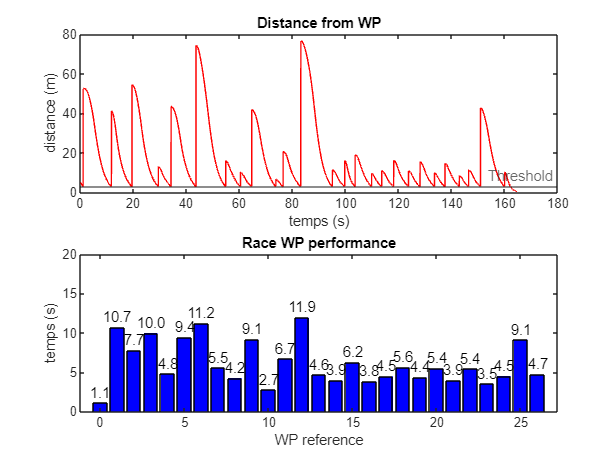


WPTimer=unique(out.WPResults.Data(:,2));
WPTimer_relative=zeros(length(WPTimer)-1, 1);
for n=1:length(WPTimer)-1
    WPTimer_relative(n)=WPTimer(n+1)-WPTimer(n);
end

figure;
subplot 211
plot(out.WPResults.Time, out.WPResults.Data(:,1), 'r');
yline(3,'-','Threshold');
xlabel('temps (s)');
ylabel('distance (m)'); title("Distance from WP");
subplot 212
wp_ref=0:26;
bar(wp_ref, WPTimer_relative, 'b');
for i = 1:length(WPTimer_relative)
    text(wp_ref(i), WPTimer_relative(i) + 1.3, sprintf('%.1f', WPTimer_relative(i)), 'HorizontalAlignment', 'center');
end
% Ajout du titre et des étiquettes des axes
title('Race WP performance');
xlabel('WP reference');
ylabel('temps (s)');
ylim([0 20]);

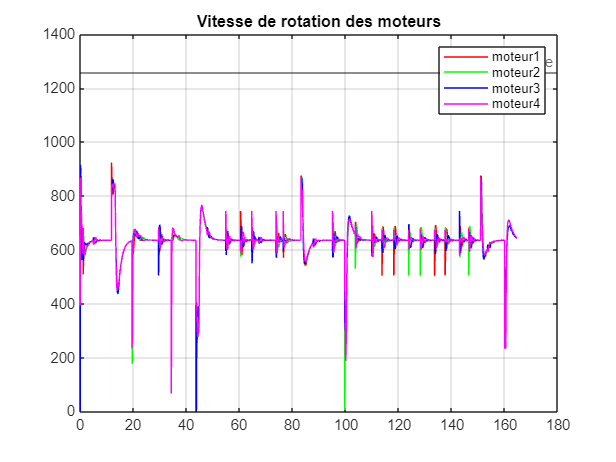



figure;
plot(out.moteurs.Time, out.moteurs.Data(:,1), 'r'); hold on;
plot(out.moteurs.Time, out.moteurs.Data(:,2), 'g');
plot(out.moteurs.Time, out.moteurs.Data(:,3), 'b');
plot(out.moteurs.Time, out.moteurs.Data(:,4), 'm');
yline(wmax,'-','Limite');
title("Vitesse de rotation des moteurs"); grid on;
legend("moteur1", "moteur2", "moteur3", "moteur4")

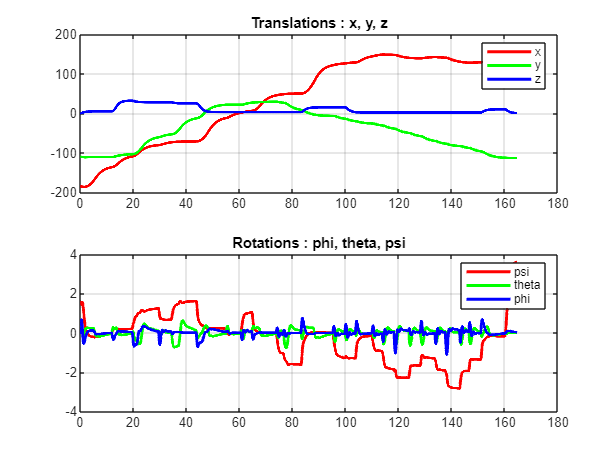

% ylim([0, 1.6])
% xlim([.15, 10])

figure;
subplot 211
plot(out.position.Time, out.position.Data(:,1), 'r', LineWidth=2); hold on;
plot(out.position.Time, out.position.Data(:,2), 'g', LineWidth=2);
plot(out.position.Time, out.position.Data(:,3), 'b', LineWidth=2);
grid on; hold off; title("Translations : x, y, z")
legend("x", "y", "z")
% ylim([-12, 47])

subplot 212
plot(out.position.Time, out.position.Data(:,4), 'r', LineWidth=2); hold on;
plot(out.position.Time, out.position.Data(:,5), 'g', LineWidth=2);
plot(out.position.Time, out.position.Data(:,6), 'b', LineWidth=2);
grid on; hold off; title("Rotations : phi, theta, psi")
legend("psi", "theta", "phi")

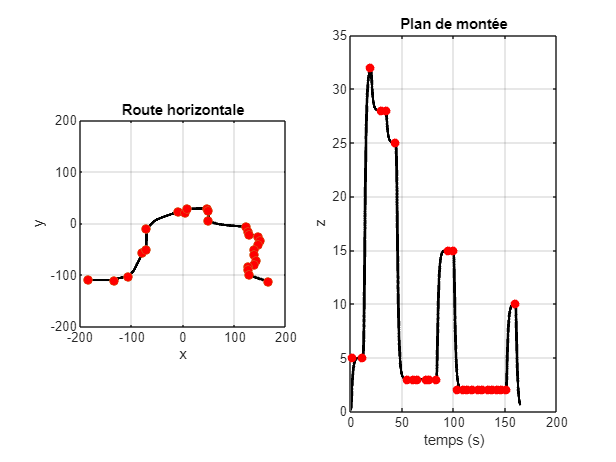

% ylim([-.4, .4])

figure;
subplot 121
plot(out.position.Data(:,1), out.position.Data(:,2), 'k', LineWidth=2); hold on; axis equal;grid on;
scatter(XYZ_Waypoints(:,1), XYZ_Waypoints(:,2), 'MarkerFaceColor', 'r');
title('Route horizontale');
xlabel('x');
ylabel('y');
ylim([-200,200]); xlim([-200,200])
subplot 122
plot(out.position.Time, out.position.Data(:,3), 'k', LineWidth=2); grid on; hold on;
now_temps=0;
for i=1:26
    now_temps=now_temps+WPTimer_relative(i);
    scatter(now_temps,XYZ_Waypoints(i,3), "filled", 'MarkerFaceColor','r');
end
title('Plan de montée');
xlabel('temps (s)');
ylabel('z');

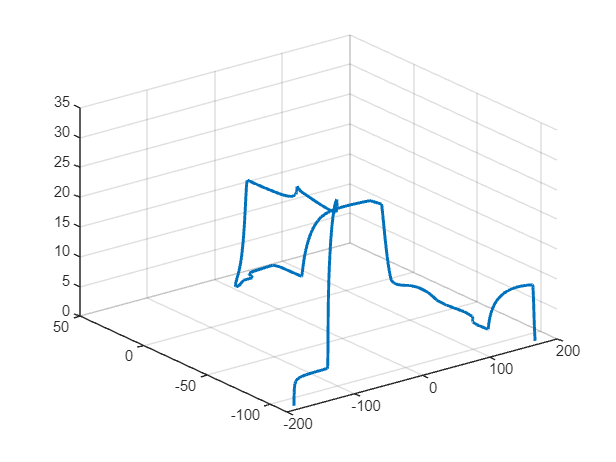


figure;
plot3(out.position.Data(:,1), out.position.Data(:,2), out.position.Data(:,3), 'LineWidth', 2); grid on;plot3(out.position.Data(:,1), out.position.Data(:,2), out.position.Data(:,3), 'LineWidth', 2); grid on; hold on;

for i=1:size(XYZ_Waypoints)
    scatter3(XYZ_Waypoints(i,1), XYZ_Waypoints(i,2), XYZ_Waypoints(i,3), "filled")
end

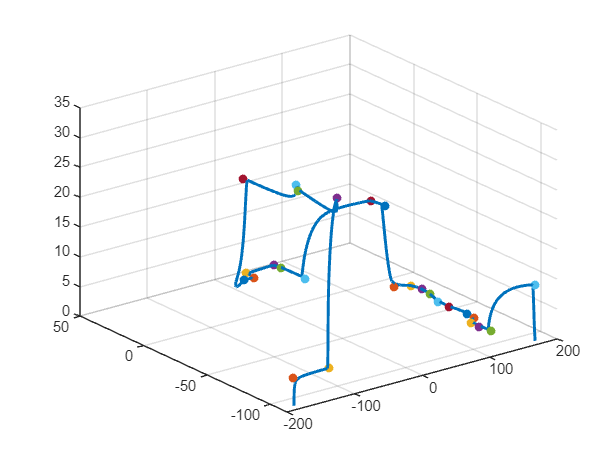

hold off;

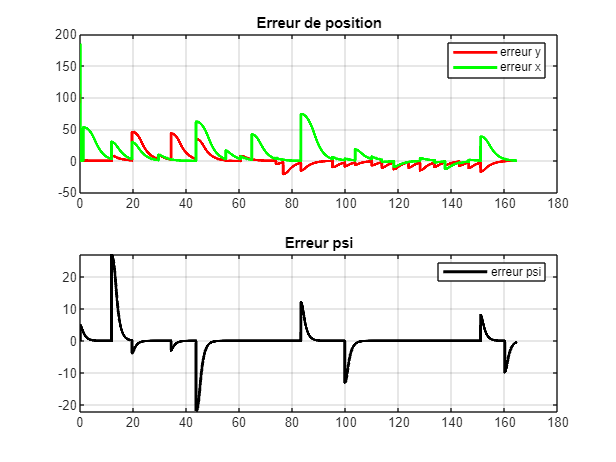


figure;
subplot 211
plot(out.erreur_pos.Time, out.erreur_pos.Data(:,1), 'r', LineWidth=2); hold on;
plot(out.erreur_pos.Time, out.erreur_pos.Data(:,2), 'g', LineWidth=2);
grid on; hold off; title("Erreur de position")
legend("erreur y", "erreur x")
% ylim([-12, 47])

subplot 212
plot(out.erreur_grande_boucle.Time, out.erreur_grande_boucle.Data(:,1), 'k', LineWidth=2); hold on;
% plot(out.position.Time, out.position.Data(:,5), 'g');
% plot(out.position.Time, out.position.Data(:,6), 'b');
grid on; hold off; title("Erreur psi")
legend("erreur psi")

% ylim([-.3, .3])

## Calcul de la distance de la course

total_distance=0;
max_distance=0;
max_waypoint=0;
min_distance=1000;
min_waypoint=0;
for i=2:size(XYZ_Waypoints)
    distance=sqrt((XYZ_Waypoints(i,1)-XYZ_Waypoints(i-1,1))^2 + (XYZ_Waypoints(i,2)-XYZ_Waypoints(i-1,2))^2 + (XYZ_Waypoints(i,3)-XYZ_Waypoints(i-1,3))^2);
    total_distance = total_distance + distance;
    if max_distance < distance
        max_distance=distance;
        max_waypoint=i-1;
    end
    if min_distance > distance
        min_distance=distance;
        min_waypoint=i-1;
    end
end

moy_distance=total_distance/26

moy_distance = 23.0993

total_distance

total_distance = 600.5819

shape = size(out.position.Data);
vitesse = zeros(shape(1), 4);
for i=2:shape(1)
    vitesse(i, 1) = (out.position.Data(i,1) - out.position.Data(i-1,1)) / (out.position.Time(i)-out.position.Time(i-1)) * 3.6;
    vitesse(i, 2) = (out.position.Data(i,2) - out.position.Data(i-1,2)) / (out.position.Time(i)-out.position.Time(i-1)) * 3.6;
    vitesse(i, 3) = (out.position.Data(i,3) - out.position.Data(i-1,3)) / (out.position.Time(i)-out.position.Time(i-1)) * 3.6;
    vitesse(i, 4) = sqrt(vitesse(i, 1)^2 + vitesse(i, 2)^2 + vitesse(i, 3)^2);
end

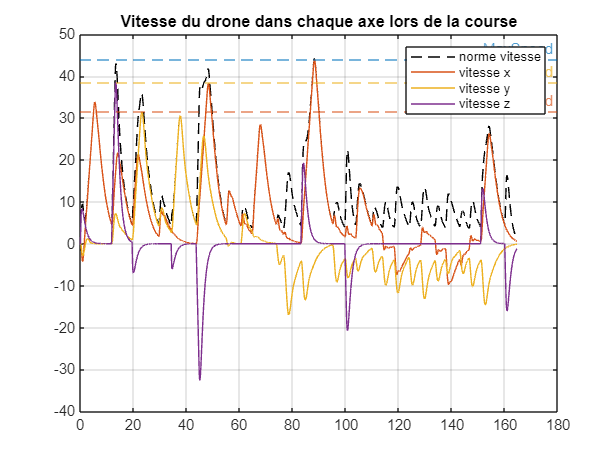


figure;
plot(out.position.Time, vitesse(:,4), 'k--');hold on; grid on;
plot(out.position.Time, vitesse(:,1));
plot(out.position.Time, vitesse(:,2));
plot(out.position.Time, vitesse(:,3));
yl1=yline(max(vitesse(:,1)), '--', "MaxSpeed"); yl1.Color='#0072BD';
yl2=yline(max(vitesse(:,2)), '--', "MaxSpeed"); yl2.Color='#D95319';
yl3=yline(max(vitesse(:,3)), '--', "MaxSpeed"); yl3.Color='#EDB120';
legend( "norme vitesse", "vitesse x", "vitesse y", "vitesse z"); title("Vitesse du drone dans chaque axe lors de la course");